searchValues=["pentane"];% 
searchType="Component";% 

ExportToExcel = true;
dispPlot =true;

% Define desired cubic equation of state
CEoSs =["PR"];

%Define the desired alpha function
alphaFunction ="Twu"; % this is the fitted alpha function
evalAlphaFunction="Soave_P"; % this must be a predictive alpha function for Comparison purposes

mainFolder="C:\Users\twaha\OneDrive\Desktop\twaha_stuff\Lakeheadu-Msc-Chemical Engineering\Thesis\notes";
% mainFolder="C:\Users\twaha\OneDrive\Desktop\twaha_stuff\Lakeheadu-Msc-Chemical Engineering\MATLAB\codes nov 4\1-optimizer\current_code\dataCalcAndPlot\PR_and_RK_data"


calcTypes =["Dp_Dv_Exp"]

calcTypes = "Dp_Dv_Exp"

%objective eqation error selection
% "rel"= squared percent relative error
% "quad" = squared quadratic error
%" mean" = squared mean error
%" MSLE" = mean squared logarithmic error
%Defining the error function

errorFunctionCalc ="AARD";

%volume Translation options
volTranslation=true;
translationApproch = "rackett";




errorFunctionPull ="MSLE";

dispTranslationInfo =true;
aggSearch=[];
if length(CEoSs)>1
    disp("Selected CEoS : "+ CEoSs(1) +" and "+ CEoSs(2))
else
    disp("Selected CEoS : "+ CEoSs(1))
end

Selected CEoS : PR


disp("Selected Alpha Function: "+ alphaFunction+" and "+ evalAlphaFunction)

Selected Alpha Function: Twu and Soave_P




if searchType =="Component"
    searchloopMax = length(searchValues);
end
dataSetsloop=1;
for CEoSLoop=1:length(CEoSs)
    CEoS=CEoSs(CEoSLoop);
    exportFolder= mainFolder+"\"+CEoS
    dataSetsloop=1;
    for searchloop=1:searchloopMax
        searchValue=searchValues(searchloop);
        [SearchOutput, groupFound, familyFound] = ComponentDatabaseSearch(aggSearch, searchValue, searchType);
        %Loops through the different families that have been selected
        for familyLoop=1:length(SearchOutput)
        
            % Obtaining the current family
            family=SearchOutput{1,familyLoop};
        
            groupNum = groupFound{1,familyLoop};
            chemFamily =familyFound{1,familyLoop};
        
            calcType="OptimalParetoSolution";
            sorceTable_FolderPath =mainFolder+"\"+CEoS+"\"+calcType+"\group_"+groupNum+"\"+chemFamily+"\"+errorFunctionPull+"\";
                 
           % Obtaining Excel files
           sorceTableExcelFiles = getAllExcelFiles(sorceTable_FolderPath);
           
            
        
            % Loops through the different components that have been selected
            for componentLoop =1:length(family)% set back to 1!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!                
               
               for sorceTableLoop=1:length(sorceTableExcelFiles)
                    % Obtaining the current component
                    componentExpData= family{1,componentLoop}; 
    
                   % Defining the current component under investigation 
                   OptParetoSol_Table = readtable(sorceTableExcelFiles{sorceTableLoop}); 
    
                if componentExpData.CAS(1)==OptParetoSol_Table.CAS(1)
                    break
                % elseif sorceTableLoop == length(family)
                %     OptParetoSol_Table=NaN;
                %     % need to add error functinaly
                end
        
               end
        
 	           ComponentInfo={componentExpData,groupNum,chemFamily};

               if CEoSLoop == 1
                   disp("Calculation Start for "+componentExpData.Component(1))

               end

                Psat_calcSet  = [];
                Venth_calcSet = [];
                Cp_calcSet    = [];
                Psat_aggErrorSet  = [];
                Venth_aggErrorSet = [];
                Cp_aggErrorSet    = [];
        
                OptParetoSol_index =OptParetoSol_Table.optParetoSol_Index(1);
        
               weightFactorLoop =OptParetoSol_index;
        
                   if isnan(OptParetoSol_Table.CalcSet(weightFactorLoop))
                        break
                   end 
        
                    weightFactor_set = [OptParetoSol_Table.W_P(weightFactorLoop),...
                                        OptParetoSol_Table.W_H(weightFactorLoop),...
                                        OptParetoSol_Table.W_Cp(weightFactorLoop)];
            
                    LeGuennecConstraints_Status=strcmpi(OptParetoSol_Table.apply_LeGuennec_constraints(1),'true');
                    
                    alphaValues =[OptParetoSol_Table.alpha_1(weightFactorLoop),...
                                  OptParetoSol_Table.alpha_2(weightFactorLoop),...
                                  OptParetoSol_Table.alpha_3(weightFactorLoop)];
        
                    %Heat capacity upper limit Reduce temperature constraint 
                    cpUpperTrLimit = OptParetoSol_Table.Cp_Tr_min(1);
        
                    
        
                    % Properties evaluated
                    evaluationProperties=rmmissing(string(OptParetoSol_Table.evaluationProperties));
            
                    OptimizationOptionsVector = {LeGuennecConstraints_Status,weightFactor_set,cpUpperTrLimit,evaluationProperties,errorFunctionCalc};
                    
                    ThermodynamicModelInfo={CEoS,alphaFunction,alphaValues,evalAlphaFunction};
            
                    % Obtaining critical properties and ideal properties of component
                    [Tc,Pc,CP_constants,mw,w,Tb,formula,vc] =   CEoS_database_manager(ComponentInfo{1}.CAS(1));
                    
                
                    HeatCapacity_Temperature        = rmmissing(componentExpData.cp_temperature_K);
                    HeatCapacity_ReduceTemperature  = rmmissing(componentExpData.cp_temperature_K)./Tc;
                    HeatCapacity_experimentalValues = rmmissing(componentExpData.cp_J_per_K_mol);
        
                    speedSound_Temperature_K        = rmmissing(componentExpData.Speed_of_Sound_Temperature_K);
                    speedSound_ReduceTemperature    = rmmissing(componentExpData.Speed_of_Sound_Temperature_K)./Tc;
                    speedSound_experimentalValues   = rmmissing(componentExpData.Speed_of_Sound_m_per_sec);
        
                    Temperature = { rmmissing(componentExpData.saturation_temperature_K),...
                                    rmmissing(componentExpData.enthalpy_vaporization_temperature_K),...
                                    HeatCapacity_Temperature(HeatCapacity_ReduceTemperature<=OptimizationOptionsVector{3}),...
                                    speedSound_Temperature_K(speedSound_ReduceTemperature<=1),... % Removes data points above critical pointata points above critical point
                                    rmmissing(componentExpData.density_gas_temperature_K),...
                                    rmmissing(componentExpData.density_liq_temperature_K),...
                                    rmmissing(componentExpData.IsothermalCompressibility_temperature_K)};
                
                    experimentalValues ={ rmmissing(componentExpData.saturation_pressure_kPa),...
                                          rmmissing(componentExpData.enthalpy_vaporization_kJ_per_mol),...
                                          HeatCapacity_experimentalValues(HeatCapacity_ReduceTemperature<=OptimizationOptionsVector{3}),...
                                          speedSound_experimentalValues(speedSound_ReduceTemperature<=1),... % Removes data points above critical pointata points above critical point
                                          rmmissing(componentExpData.density_gas_kg_per_m3),...
                                          rmmissing(componentExpData.density_liq_kg_per_m3),...
                                          rmmissing(componentExpData.IsothermalCompressibility_per_kPa)};
                    
                    denLiq_data={Temperature{6},experimentalValues{6}};  
                    % isempty(denLiq_data{1})||isempty(denLiq_data{2})
                    translationOptionsVector={volTranslation,denLiq_data,translationApproch,dispTranslationInfo};
   
                    
                    [Psat_data,Venth_data,Cp_data,Cv_data,soundSpeed_data,soundSpeedVT_data,denGas_data,denGasVT_data,denLiq_data,denLiqVT_data,c,predCalcRange_Temp_data,dP_dV_predSet_data,dP_dT_predSet_data,beta_predSet_data,war_predSet_data]=setCalc(ComponentInfo,Temperature,experimentalValues,ThermodynamicModelInfo,OptimizationOptionsVector,translationOptionsVector,calcTypes);
                    
                        
                    Psat_calcSet        = Psat_data(:,1:4);
                    Venth_calcSet       = Venth_data(:,1:4);
                    Cp_calcSet          = Cp_data(:,1:4);
                    soundSpeed_calcSet  = soundSpeed_data(:,1:4);
                    soundSpeedVT_calcSet  = soundSpeedVT_data(:,1:4);
                    denGas_calcSet  = denGas_data(:,1:4);
                    denGasVT_calcSet  = denGasVT_data(:,1:4);            
                    denLiq_calcSet  = denLiq_data(:,1:4);
                    denLiqVT_calcSet  = denLiqVT_data(:,1:4); 
        
                    Psat_aggErrorSet = Psat_data(1,5:6);
                    Venth_aggErrorSet = Venth_data(1,5:6);
                    Cp_aggErrorSet = Cp_data(1,5:6);
                    denGas_aggErrorSet = denGas_data(1,5:6);
                    denGasVT_aggErrorSet = denGasVT_data(1,5:6);
                    denLiq_aggErrorSet = denLiq_data(1,5:6);
                    denLiqVT_aggErrorSet = denLiqVT_data(1,5:6);

exportFolder = "C:\Users\twaha\OneDrive\Desktop\twaha_stuff\Lakeheadu-Msc-Chemical Engineering\Thesis\notes\PR"

Calculation Start for pentane


 
 Iteration   Func-count         f(x)         Procedure
     0            1          258.516         
     1            2          258.516         initial simplex
     2            4          173.287         expand
     3            6          63.7925         expand
     4            8         0.177718         expand
     5           10         0.177718         contract outside
     6           12         0.177718         contract inside
     7           14         0.064413         contract inside
     8           16       0.00996315         contract inside
     9           18       0.00996315         contract inside
    10           20       0.00406309         contract inside
    11           22       0.00406309         contract inside
    12           24       0.00406309         contract inside
    13           26       0.00405938         contract inside
    14           28       0.00403509         contract inside
    15           30       0.00403509         contract inside
    16  

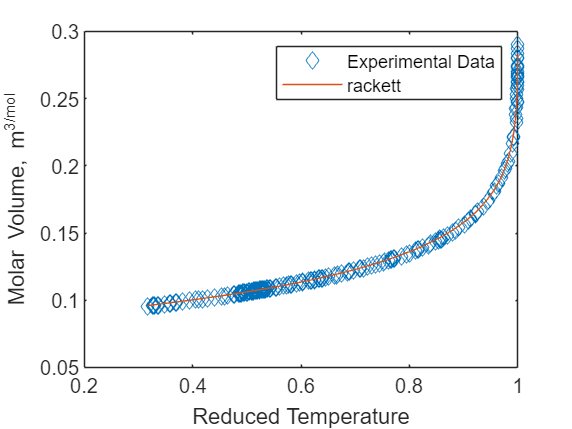

 
 Iteration   Func-count         f(x)         Procedure
     0            1      6.37452e-06         
     1            2      6.37452e-06         initial simplex
     2            4      4.09974e-06         expand
     3            6      1.05017e-06         expand
     4            8      6.14065e-10         reflect
     5           10      6.14065e-10         contract outside
     6           12      6.14065e-10         contract inside
     7           14      6.14065e-10         contract inside
     8           16      6.14065e-10         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 

 
 Iteration   Func-count         f(x)         Procedure
     0            1          258.516         
     1            2          258.516         initial simplex
     2            4          173.287         expand
     3            6  

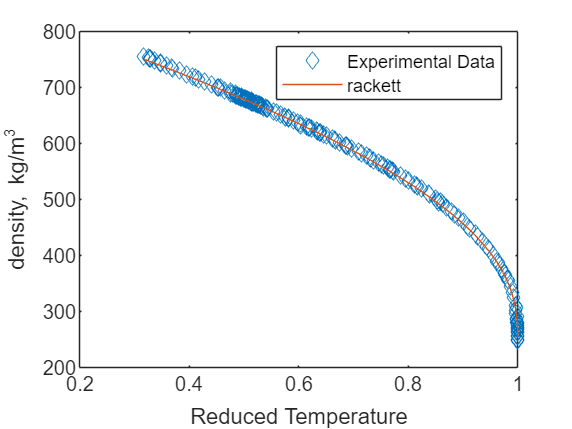

 
 Iteration   Func-count         f(x)         Procedure
     0            1      6.94604e-06         
     1            2      6.94604e-06         initial simplex
     2            4       4.5605e-06         expand
     3            6      1.28944e-06         expand
     4            8      1.83693e-08         reflect
     5           10      1.83693e-08         contract outside
     6           12      1.31026e-08         contract inside
     7           14       1.1095e-10         contract inside
     8           16       1.1095e-10         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


Unrecognized function or variable 'Zra'.

Error in property_calculator_v8>setCalc (line 832)
        vLsat_opt_mL_per_mol = (R * Tc / Pc) * (Zra).^ (1 + (1 - (Cv_ExpClc_temp./Tc)).^(2/7));

    dataCell ={};
    calcTracker= {};
   if ismember("P", calcTypes)        
                    PsatMaxRow=max([length(Temperature{1}),length(experimentalValues{1}),length(predCalcRange_Temp_data),height(Psat_data)]);
                    Psat_expTemp =extendTable(table(Temperature{1},VariableNames={'Exp_pressureTemperature_K'}),PsatMaxRow);
                    Psat_expTr =extendTable(table(Temperature{1}./Tc,VariableNames={'Exp_pressureReduceTemperature'}),PsatMaxRow);
                    Psat_exp =extendTable(table(experimentalValues{1},VariableNames={'Exp_pressure_kPa'}),PsatMaxRow);
                    Psat_calc =extendTable(table(Psat_data{:,1},Psat_data{:,2},VariableNames={char(alphaFunction+"Calc_pressure_kPa"),char(evalAlphaFunction+"Calc_pressure_kPa")}),PsatMaxRow);                
                    Psat_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_pressureTemperature_K'}),PsatMaxRow);
                    Psat_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_pressureReduceTemperature'}),PsatMaxRow);
                    Psat_pred =extendTable(table(Psat_data{:,7},Psat_data{:,8},VariableNames={char(alphaFunction+"_Pred_pressure_kPa"),char(evalAlphaFunction+"_Pred_pressure_kPa")}),PsatMaxRow);
                    Psat_axisNaming=extendTable(table(["Saturation Pressure, kPa";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),PsatMaxRow);
                    Psat_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),PsatMaxRow);
                    Psat_plotingData =[Psat_expTemp,Psat_expTr,Psat_exp,Psat_calc,Psat_predTemp,Psat_predTr,Psat_pred,Psat_axisNaming,Psat_legendNaming];
                    dataCell{end+1} = Psat_plotingData;
                    calcTracker{end+1}  ="P";
   end  

   if ismember("H", calcTypes)        
                    VenthMaxRow=max([length(Temperature{2}),length(experimentalValues{2}),length(predCalcRange_Temp_data),height(Venth_data)]);
                    Venth_expTemp =extendTable(table(Temperature{2},VariableNames={'Exp_vaporizationTemperature_K'}),VenthMaxRow);
                    Venth_expTr =extendTable(table(Temperature{2}./Tc,VariableNames={'Exp_vaporizationReduceTemperature'}),VenthMaxRow);
                    Venth_exp =extendTable(table(experimentalValues{2},VariableNames={'Exp_vaporization_kJ_per_mol'}),VenthMaxRow);
                    Venth_calc =extendTable(table(Venth_data{:,1},Venth_data{:,2},VariableNames={char(alphaFunction+"Calc_vaporization_kJ_per_mol"),char(evalAlphaFunction+"Calc_vaporization_kJ_per_mol")}),VenthMaxRow);                
                    Venth_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_vaporizationTemperature_K'}),VenthMaxRow);
                    Venth_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_vaporizationReduceTemperature'}),VenthMaxRow);
                    Venth_pred =extendTable(table(Venth_data{:,7},Venth_data{:,8},VariableNames={char(alphaFunction+"_Pred_density_vaporization_kJ_per_mol"),char(evalAlphaFunction+"_Pred_vaporization_kJ_per_mol")}),VenthMaxRow);
                    Venth_axisNaming=extendTable(table(["Vaporization Enthalpy, kJ mol^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),VenthMaxRow);
                    Venth_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),VenthMaxRow);
                    Venth_plotingData =[Venth_expTemp,Venth_expTr,Venth_exp,Venth_calc,Venth_predTemp,Venth_predTr,Venth_pred,Venth_axisNaming,Venth_legendNaming];
                    dataCell{end+1} = Venth_plotingData;
                    calcTracker{end+1}  ="H";
   end   

   if ismember("Cp", calcTypes)        
        Cp_temp=rmmissing(componentExpData.cp_temperature_K);
        Cp_exp=rmmissing(componentExpData.cp_J_per_K_mol);
                    CpMaxRow=max([length(Cp_temp),length(Cp_exp),length(predCalcRange_Temp_data),height(Cp_data)]);
                    Cp_expTemp =extendTable(table(Cp_temp,VariableNames={'Exp_heatCapacity_CpTemperature_K'}),CpMaxRow);
                    Cp_expTr =extendTable(table(Cp_temp./Tc,VariableNames={'Exp_heatCapacity_CpReduceTemperature'}),CpMaxRow);
                    Cp_exp =extendTable(table(Cp_exp,VariableNames={'Exp_heatCapacity_Cp_J_per_mol_K'}),CpMaxRow);
                    Cp_calc =extendTable(table(Cp_data{:,1},Cp_data{:,2},VariableNames={char(alphaFunction+"Calc_heatCapacity_Cp_J_per_mol_K"),char(evalAlphaFunction+"Calc_heatCapacity_Cp_J_per_mol_K")}),CpMaxRow);                
                    Cp_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_heatCapacity_CpTemperature_K'}),CpMaxRow);
                    Cp_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_heatCapacity_CpReduceTemperature'}),CpMaxRow);
                    Cp_pred =extendTable(table(Cp_data{:,7},Cp_data{:,8},VariableNames={char(alphaFunction+"_Pred_density_heatCapacity_Cp_J_per_mol_K"),char(evalAlphaFunction+"_Pred_heatCapacity_Cp_J_per_mol_K")}),CpMaxRow);
                    Cp_axisNaming=extendTable(table(["Heat Capacity at Constant Pressure, J mol^-1 K^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),CpMaxRow);
                    Cp_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),CpMaxRow);
                    Cp_plotingData =[Cp_expTemp,Cp_expTr,Cp_exp,Cp_calc,Cp_predTemp,Cp_predTr,Cp_pred,Cp_axisNaming,Cp_legendNaming];
                    dataCell{end+1} = Cp_plotingData;
                    calcTracker{end+1}  ="Cp";

                    
   end   

   if ismember("Cv", calcTypes)        

                    CvMaxRow=max([length(predCalcRange_Temp_data),height(Cv_data)]);
                    Cv_expTemp =extendTable(table(nan,VariableNames={'Exp_heatCapacity_Cv_Temperature_K'}),CvMaxRow);
                    Cv_expTr =extendTable(table(nan,VariableNames={'Exp_heatCapacity_Cv_ReduceTemperature'}),CvMaxRow);
                    Cv_exp =extendTable(table(nan,VariableNames={'Exp_heatCapacity_Cv_J_per_mol_K'}),CvMaxRow);
                    Cv_calc =extendTable(table(nan,nan,VariableNames={char(alphaFunction+"Calc_heatCapacity_Cv_J_per_mol_K"),char(evalAlphaFunction+"Calc_heatCapacity_Cv_J_per_mol_K")}),CvMaxRow);                
                    Cv_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_heatCapacity_CvTemperature_K'}),CvMaxRow);
                    Cv_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_heatCapacity_CvReduceTemperature'}),CvMaxRow);
                    Cv_pred =extendTable(table(Cv_data{:,7},Cv_data{:,8},VariableNames={char(alphaFunction+"_Pred_density_heatCapacity_Cv_J_per_mol_K"),char(evalAlphaFunction+"_Pred_heatCapacity_Cv_J_per_mol_K")}),CvMaxRow);
                    Cv_axisNaming=extendTable(table(["heat Capacity at Constant Volume, J mol^-1 K^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),CvMaxRow);
                    Cv_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),CvMaxRow);
                    Cv_plotingData =[Cv_expTemp,Cv_expTr,Cv_exp,Cv_calc,Cv_predTemp,Cv_predTr,Cv_pred,Cv_axisNaming,Cv_legendNaming];
                    dataCell{end+1} = Cv_plotingData;
                    calcTracker{end+1}  ="Cv";
   end   



   if ismember("dl", calcTypes)        
                    denLiqMaxRow=max([length(Temperature{6}),length(experimentalValues{6}),length(predCalcRange_Temp_data),height(denLiq_data)]);
                    denLiq_expTemp =extendTable(table(Temperature{6},VariableNames={'Exp_liqDensityTemperature_K'}),denLiqMaxRow);
                    denLiq_expTr =extendTable(table(Temperature{6}./Tc,VariableNames={'Exp_liqDensityReduceTemperature'}),denLiqMaxRow);
                    denLiq_exp =extendTable(table(experimentalValues{6},VariableNames={'Exp_liqDensity_kg_per_m3'}),denLiqMaxRow);
                    denLiq_calc =extendTable(table(denLiq_data{:,1},denLiq_data{:,2},VariableNames={char(alphaFunction+"Calc_liqDensityq_kg_per_m3"),char(evalAlphaFunction+"Calc_liqDensity_kg_per_m3")}),denLiqMaxRow);                
                    denLiq_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_liqDensityTemperature_K'}),denLiqMaxRow);
                    denLiq_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_liqDensityReduceTemperature'}),denLiqMaxRow);
                    denLiq_pred =extendTable(table(denLiq_data{:,7},denLiq_data{:,8},VariableNames={char(alphaFunction+"_Pred_density_liq_kg_per_m3"),char(evalAlphaFunction+"_Pred_liqDensity_kg_per_m3")}),denLiqMaxRow);
                    denLiq_axisNaming=extendTable(table(["Liquid density ,kg m^-3";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),denLiqMaxRow);
                    denLiq_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),denLiqMaxRow);
                    denLiq_plotingData =[denLiq_expTemp,denLiq_expTr,denLiq_exp,denLiq_calc,denLiq_predTemp,denLiq_predTr,denLiq_pred,denLiq_axisNaming,denLiq_legendNaming];
                    dataCell{end+1} = denLiq_plotingData;
                    calcTracker{end+1}  ="dl";

        if volTranslation

                    denLiqVTMaxRow=max([length(Temperature{6}),length(experimentalValues{6}),length(predCalcRange_Temp_data),height(denLiqVT_data)]);
                    denLiqVT_expTemp =extendTable(table(Temperature{6},VariableNames={'Exp_liqDensityTemperature_K'}),denLiqVTMaxRow);
                    denLiqVT_expTr =extendTable(table(Temperature{6}./Tc,VariableNames={'Exp_liqDensityReduceTemperature'}),denLiqVTMaxRow);
                    denLiqVT_exp =extendTable(table(experimentalValues{6},VariableNames={'Exp_liqDensityVT_kg_per_m3'}),denLiqVTMaxRow);
                    denLiqVT_calc =extendTable(table(denLiqVT_data{:,1},denLiqVT_data{:,2},VariableNames={char(alphaFunction+"Calc_liqDensityVT_kg_per_m3"),char(evalAlphaFunction+"Calc_liqDensityVT_kg_per_m3")}),denLiqVTMaxRow);                
                    denLiqVT_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_liqDensityTemperature_K'}),denLiqVTMaxRow);
                    denLiqVT_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_liqDensityReduceTemperature'}),denLiqVTMaxRow);
                    denLiqVT_pred =extendTable(table(denLiqVT_data{:,7},denLiqVT_data{:,8},VariableNames={char(alphaFunction+"_Pred_liqDensityVT_kg_per_m3"),char(evalAlphaFunction+"_Pred_liqDensityVT_kg_per_m3")}),denLiqVTMaxRow);
                    denLiqVT_axisNaming=extendTable(table(["Translated Liquid density ,kg m^-3";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),denLiqVTMaxRow);
                    denLiqVT_legendNaming=extendTable(table([componentExpData.Component(1)+"VT-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),denLiqVTMaxRow);
                    denLiqVT_plotingData =[denLiqVT_expTemp,denLiqVT_expTr,denLiqVT_exp,denLiqVT_calc,denLiqVT_predTemp,denLiqVT_predTr,denLiqVT_pred,denLiqVT_axisNaming,denLiqVT_legendNaming];
                    dataCell{end+1} = denLiqVT_plotingData;
                    calcTracker{end+1}  ="vt_dl";
        end

   end

   if ismember("dg", calcTypes)     
                    denGasMaxRow=max([length(Temperature{5}),length(experimentalValues{5}),length(predCalcRange_Temp_data),height(denGas_data)]);
                    denGas_expTemp =extendTable(table(Temperature{5},VariableNames={'Exp_gasDensityTemperature_K'}),denGasMaxRow);
                    denGas_expTr =extendTable(table(Temperature{5}./Tc,VariableNames={'Exp_gasDensityReduceTemperature'}),denGasMaxRow);
                    denGas_exp =extendTable(table(experimentalValues{5},VariableNames={'Exp_gasDensity_Gas_kg_per_m3'}),denGasMaxRow);
                    denGas_calc =extendTable(table(denGas_data{:,1},denGas_data{:,2},VariableNames={char(alphaFunction+"Calc_gasDensity_kg_per_m3"),char(evalAlphaFunction+"Calc_gasDensity_kg_per_m3")}),denGasMaxRow);                
                    denGas_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_gasDensityTemperature_K'}),denGasMaxRow);
                    denGas_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_gasDensityReduceTemperature'}),denGasMaxRow);
                    denGas_pred =extendTable(table(denGas_data{:,7},denGas_data{:,8},VariableNames={char(alphaFunction+"_Pred_gasDensity_kg_per_m3"),char(evalAlphaFunction+"_Pred_gasDensity_kg_per_m3")}),denGasMaxRow);
                    denGas_axisNaming=extendTable(table(["Gas Density ,kg m^-3";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),denGasMaxRow);
                    denGas_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),denGasMaxRow);
                    denGas_plotingData =[denGas_expTemp,denGas_expTr,denGas_exp,denGas_calc,denGas_predTemp,denGas_predTr,denGas_pred,denGas_axisNaming,denGas_legendNaming];
                    dataCell{end+1} = denGas_plotingData;
                    calcTracker{end+1}  ="dg";

        if volTranslation

                    denGasVTMaxRow=max([length(Temperature{5}),length(experimentalValues{5}),length(predCalcRange_Temp_data),height(denGasVT_data)]);
                    denGasVT_expTemp =extendTable(table(Temperature{5},VariableNames={'Exp_gasDensityTemperature_K'}),denGasVTMaxRow);
                    denGasVT_expTr =extendTable(table(Temperature{5}./Tc,VariableNames={'Exp_gasDensityReduceTemperature'}),denGasVTMaxRow);
                    denGasVT_exp =extendTable(table(experimentalValues{5},VariableNames={'Exp_gasDensityVT_kg_per_m3'}),denGasVTMaxRow);
                    denGasVT_calc =extendTable(table(denGasVT_data{:,1},denGasVT_data{:,2},VariableNames={char(alphaFunction+"Calc_gasDensityVT_kg_per_m3"),char(evalAlphaFunction+"Calc_gasDensityVT_kg_per_m3")}),denGasVTMaxRow);                
                    denGasVT_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_gasDensityTemperature_K'}),denGasVTMaxRow);
                    denGasVT_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_gasDensityReduceTemperature'}),denGasVTMaxRow);
                    denGasVT_pred =extendTable(table(denGasVT_data{:,7},denGasVT_data{:,8},VariableNames={char(alphaFunction+"_Pred_gasDensityVT_kg_per_m3"),char(evalAlphaFunction+"_Pred_gasDensityVT_kg_per_m3")}),denGasVTMaxRow);
                    denGasVT_axisNaming=extendTable(table(["Translated Gas Density ,kg/m^-3";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),denGasVTMaxRow);
                    denGasVT_legendNaming=extendTable(table([componentExpData.Component(1)+"VT-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),denGasVTMaxRow);
                    denGasVT_plotingData =[denGasVT_expTemp,denGasVT_expTr,denGasVT_exp,denGasVT_calc,denGasVT_predTemp,denGasVT_predTr,denGasVT_pred,denGasVT_axisNaming,denGasVT_legendNaming]; 
                    dataCell{end+1} = denGasVT_plotingData;
                    calcTracker{end+1}  ="vt_dg";
        end

   end
    if ismember("u", calcTypes)     
                    soundSpeedMaxRow=max([length(Temperature{4}),length(experimentalValues{4}),length(predCalcRange_Temp_data),height(soundSpeed_data)]);
                    soundSpeed_expTemp =extendTable(table(Temperature{4},VariableNames={'Exp_soundSpeedTemperature_K'}),soundSpeedMaxRow);
                    soundSpeed_expTr =extendTable(table(Temperature{4}./Tc,VariableNames={'Exp_soundSpeedReduceTemperature'}),soundSpeedMaxRow);
                    soundSpeed_exp =extendTable(table(experimentalValues{4},VariableNames={'Exp_soundSpeed_m_per_sec'}),soundSpeedMaxRow);
                    soundSpeed_calc =extendTable(table(soundSpeed_data{:,1},soundSpeed_data{:,2},VariableNames={char(alphaFunction+"_Calc_soundSpeed_m_per_sec"),char(evalAlphaFunction+"_Calc_soundSpeed_m_per_sec")}),soundSpeedMaxRow);                
                    soundSpeed_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_soundSpeedTemperature_K'}),soundSpeedMaxRow);
                    soundSpeed_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_soundSpeedReduceTemperature'}),soundSpeedMaxRow);
                    soundSpeed_pred =extendTable(table(soundSpeed_data{:,7},soundSpeed_data{:,8},VariableNames={char(alphaFunction+"_Pred_soundSpeed_m_per_sec"),char(evalAlphaFunction+"_Pred_soundSpeed_m_per_sec")}),soundSpeedMaxRow);
                    soundSpeed_axisNaming=extendTable(table(["speed of sound, m s^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'soundSpeed_y_x1_x2_axisNames'}),soundSpeedMaxRow);
                    soundSpeed_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'soundSpeed_legendNaming'}),soundSpeedMaxRow);
                    soundSpeed_plotingData =[soundSpeed_expTemp,soundSpeed_expTr,soundSpeed_exp,soundSpeed_calc,soundSpeed_predTemp,soundSpeed_predTr,soundSpeed_pred,soundSpeed_axisNaming,soundSpeed_legendNaming];
                    dataCell{end+1} = soundSpeed_plotingData;
                    calcTracker{end+1}  ="u";
                    

        if volTranslation

                    soundSpeedVTMaxRow=max([length(Temperature{4}),length(experimentalValues{4}),length(predCalcRange_Temp_data),height(soundSpeedVT_data)]);
                    soundSpeedVT_expTemp =extendTable(table(Temperature{4},VariableNames={'Exp_VTsoundSpeedTemperature_K'}),soundSpeedVTMaxRow);
                    soundSpeedVT_expTr =extendTable(table(Temperature{4}./Tc,VariableNames={'Exp_VTsoundSpeedReduceTemperature'}),soundSpeedVTMaxRow);
                    soundSpeedVT_exp =extendTable(table(experimentalValues{4},VariableNames={'Exp_VTsoundSpeed_m_per_sec'}),soundSpeedVTMaxRow);
                    soundSpeedVT_calc =extendTable(table(soundSpeedVT_data{:,1},soundSpeedVT_data{:,2},VariableNames={char(alphaFunction+"_Calc_VTsoundSpeed_m_per_sec"),char(evalAlphaFunction+"_Calc_VTsoundSpeed_m_per_sec")}),soundSpeedVTMaxRow);                
                    soundSpeedVT_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_VTsoundSpeedTemperature_K'}),soundSpeedVTMaxRow);
                    soundSpeedVT_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_VTsoundSpeedReduceTemperature'}),soundSpeedVTMaxRow);
                    soundSpeedVT_pred =extendTable(table(soundSpeedVT_data{:,7},soundSpeedVT_data{:,8},VariableNames={char(alphaFunction+"_Pred_VTsoundSpeed_m_per_sec"),char(evalAlphaFunction+"_Pred_VTsoundSpeed_m_per_sec")}),soundSpeedVTMaxRow);
                    soundSpeedVT_axisNaming=extendTable(table(["Volume translated speed of sound, m s^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'soundSpeedVT_y_x1_x2_axisNames'}),soundSpeedVTMaxRow);
                    soundSpeedVT_legendNaming=extendTable(table([componentExpData.Component(1)+"VT-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'soundSpeedVT_legendNaming'}),soundSpeedVTMaxRow);
                    soundSpeedVT_plotingData =[soundSpeedVT_expTemp,soundSpeedVT_expTr,soundSpeedVT_exp,soundSpeedVT_calc,soundSpeedVT_predTemp,soundSpeedVT_predTr,soundSpeedVT_pred,soundSpeedVT_axisNaming,soundSpeedVT_legendNaming];
                    dataCell{end+1} = soundSpeedVT_plotingData;
                    calcTracker{end+1}  ="vt_u";
        end


    end

   if ismember("w", calcTypes)        
                    warMaxRow=max([length(Temperature{1}),length(experimentalValues{1}),length(predCalcRange_Temp_data),height(war_predSet_data)]);
                    war_expTemp =extendTable(table(NaN,VariableNames={'Exp_waringTemperature_K'}),warMaxRow);
                    war_expTr =extendTable(table(NaN,VariableNames={'Exp_waringReduceTemperature'}),warMaxRow);
                    war_exp =extendTable(table(NaN,VariableNames={'Exp_waring_J_per_mol_K'}),warMaxRow);
                    war_calc =extendTable(table(NaN,NaN,VariableNames={char(alphaFunction+"Calc_waring_per_waringMin"),char(evalAlphaFunction+"Calc_waring_per_waringMin")}),warMaxRow);                
                    war_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_waring_per_waringMinTemperature_K'}),warMaxRow);
                    war_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_waring_per_waringMinReduceTemperature'}),warMaxRow);
                    war_pred =extendTable(table(war_predSet_data{:,1}./min(war_predSet_data{:,1}),war_predSet_data{:,2}./min(war_predSet_data{:,2}),...
                        VariableNames={char(alphaFunction+"_Pred_density_waring_per_waring_per_waringMin"),char(evalAlphaFunction+"_Pred_waring_per_waring_per_waringMin")}),warMaxRow);
                    war_axisNaming=extendTable(table(["Waring Number / Minimum Waring Number";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),warMaxRow);
                    war_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),warMaxRow);
                    war_plotingData =[war_expTemp,war_expTr,war_exp,war_calc,war_predTemp,war_predTr,war_pred,war_axisNaming,war_legendNaming];
                    dataCell{end+1} = war_plotingData;
                    calcTracker{end+1}  ="w";
   end    

   if ismember("dP_dV", calcTypes)        
                    dP_dVMaxRow=max([length(Temperature{1}),length(experimentalValues{1}),length(predCalcRange_Temp_data),height(dP_dV_predSet_data)]);
                    dP_dV_expTemp =extendTable(table(NaN,VariableNames={'Exp_dP_dV_Temperature_K'}),dP_dVMaxRow);
                    dP_dV_expTr =extendTable(table(NaN,VariableNames={'Exp_dP_dV_ReduceTemperature'}),dP_dVMaxRow);
                    dP_dV_exp =extendTable(table(NaN,VariableNames={'Exp_dP_dV_kPa_mol_per_m3'}),dP_dVMaxRow);
                    dP_dV_calc =extendTable(table(NaN,NaN,VariableNames={char(alphaFunction+"Calc_dP_dV"),char(evalAlphaFunction+"Calc_dP_dV")}),dP_dVMaxRow);                
                    dP_dV_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_dP_dV_Temperature_K'}),dP_dVMaxRow);
                    dP_dV_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_dP_dV_ReduceTemperature'}),dP_dVMaxRow);
                    dP_dV_pred =extendTable(table(dP_dV_predSet_data{:,1},dP_dV_predSet_data{:,2},VariableNames={char(alphaFunction+"_Pred_density_dP_dV"),char(evalAlphaFunction+"_Pred_dP_dV")}),dP_dVMaxRow);
                    dP_dV_axisNaming=extendTable(table(["dP_dV kPa mol";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),dP_dVMaxRow);
                    dP_dV_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),dP_dVMaxRow);
                    dP_dV_plotingData =[dP_dV_expTemp,dP_dV_expTr,dP_dV_exp,dP_dV_calc,dP_dV_predTemp,dP_dV_predTr,dP_dV_pred,dP_dV_axisNaming,dP_dV_legendNaming];
                    dataCell{end+1} = dP_dV_plotingData;
                    calcTracker{end+1}  ="dP_dV";
   end     

   if ismember("dP_dT", calcTypes)        
                    dP_dTMaxRow=max([length(Temperature{1}),length(experimentalValues{1}),length(predCalcRange_Temp_data),height(dP_dT_predSet_data)]);
                    dP_dT_expTemp =extendTable(table(NaN,VariableNames={'Exp_dP_dT_Temperature_K'}),dP_dTMaxRow);
                    dP_dT_expTr =extendTable(table(NaN,VariableNames={'Exp_dP_dT_ReduceTemperature'}),dP_dTMaxRow);
                    dP_dT_exp =extendTable(table(NaN,VariableNames={'Exp_dP_dT_kPa_per_K'}),dP_dTMaxRow);
                    dP_dT_calc =extendTable(table(NaN,NaN,VariableNames={char(alphaFunction+"Calc_dP_dT"),char(evalAlphaFunction+"Calc_dP_dT")}),dP_dTMaxRow);                
                    dP_dT_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_dP_dT_Temperature_K'}),dP_dTMaxRow);
                    dP_dT_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_dP_dT_ReduceTemperature'}),dP_dTMaxRow);
                    dP_dT_pred =extendTable(table(dP_dT_predSet_data{:,1},dP_dT_predSet_data{:,2},VariableNames={char(alphaFunction+"_Pred_density_dP_dT"),char(evalAlphaFunction+"_Pred_dP_dT")}),dP_dTMaxRow);
                    dP_dT_axisNaming=extendTable(table(["dP_dT, kPa K^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),dP_dTMaxRow);
                    dP_dT_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),dP_dTMaxRow);
                    dP_dT_plotingData =[dP_dT_expTemp,dP_dT_expTr,dP_dT_exp,dP_dT_calc,dP_dT_predTemp,dP_dT_predTr,dP_dT_pred,dP_dT_axisNaming,dP_dT_legendNaming];
                    dataCell{end+1} = dP_dT_plotingData;
                    calcTracker{end+1}  ="dP_dT";
   end

   if ismember("b", calcTypes)        
                    betaMaxRow=max([length(Temperature{1}),length(experimentalValues{1}),length(predCalcRange_Temp_data),height(beta_predSet_data)]);
                    beta_expTemp =extendTable(table(NaN,VariableNames={'Exp_beta_Temperature_K'}),betaMaxRow);
                    beta_expTr =extendTable(table(NaN,VariableNames={'Exp_beta_ReduceTemperature'}),betaMaxRow);
                    beta_exp =extendTable(table(NaN,VariableNames={'Exp_beta'}),betaMaxRow);
                    beta_calc =extendTable(table(NaN,NaN,VariableNames={char(alphaFunction+"Calc_beta"),char(evalAlphaFunction+"Calc_beta")}),betaMaxRow);                
                    beta_predTemp =extendTable(table(predCalcRange_Temp_data,VariableNames={'Pred_beta_Temperature_K'}),betaMaxRow);
                    beta_predTr =extendTable(table(predCalcRange_Temp_data./Tc,VariableNames={'Pred_beta_ReduceTemperature'}),betaMaxRow);
                    beta_pred =extendTable(table(beta_predSet_data{:,1},beta_predSet_data{:,2},VariableNames={char(alphaFunction+"_Pred_density_beta"),char(evalAlphaFunction+"_Pred_beta")}),betaMaxRow);
                    beta_axisNaming=extendTable(table(["beta, kPa^-1";"Temperature, K";"Reduce Temperature"],VariableNames={'y_x1_x2_axisNames'}),betaMaxRow);
                    beta_legendNaming=extendTable(table([componentExpData.Component(1)+"-"+CEoS;alphaFunction;evalAlphaFunction],VariableNames={'legendNaming'}),betaMaxRow);
                    beta_plotingData =[beta_expTemp,beta_expTr,beta_exp,beta_calc,beta_predTemp,beta_predTr,beta_pred,beta_axisNaming,beta_legendNaming];
                    dataCell{end+1} = beta_plotingData;
                    calcTracker{end+1}  ="b";                    
   end     
   
            end
        
        end
    dataSets(dataSetsloop,CEoSLoop)={dataCell};    

    dataSetsloop=dataSetsloop+1;
    end
    calcTracker=string(calcTracker);

end


if dispPlot 
    plotDate(dataSets,calcTracker)
end

if ExportToExcel

    ExportDataToExcel(dataSets,exportFolder,searchValues)
end

function [Psat_data,Venth_data,Cp_data,Cv_data,soundSpeed,soundSpeedVT,denGas,denGasVT,denLiq,denLiqVT,c,predCalcRange_Temp,dP_dV_predSet,dP_dT_predSet,beta_predSet,war_predSet]=setCalc(ComponentInfo,Temperature,experimentalValues,ThermodynamicModelInfo,OptimizationOptionsVector,translationOptionsVector,calcTypes)

    % Obtaining critical properties and ideal properties of component
    [Tc,Pc,CP_constants,mw,w,~,~,vc]=CEoS_database_manager(ComponentInfo{1}.CAS(1));
    R = 8.314;
    alphaConstants=ThermodynamicModelInfo{3};

    CEoS=ThermodynamicModelInfo{1};
    alphaFunction =ThermodynamicModelInfo{2};
    evalAlphaFunction =ThermodynamicModelInfo{4};
    
    % Obtaining Translation Options
    volTranslation      =   translationOptionsVector{1};
    rhoData             =   translationOptionsVector{2};
    translationApproch  =   translationOptionsVector{3};    
    dispTranslationInfo =   translationOptionsVector{4};

    % Calculating corresponding alpha parameters
    [alphaConstants]=alpha_parm_clc(alphaFunction,CEoS,w,alphaConstants);
    
    % Calculating corresponding alpha parameters
    [evalAlphaConstants]=alpha_parm_clc(evalAlphaFunction,CEoS,w,alphaConstants);

    % creating a vector containing pure comp properties; used to solve EOS
    [VECTOR_PROPERTIES_PURE_COMP_Translation]= [Tc,Pc,alphaConstants,CP_constants,mw,volTranslation,w,vc];
    [VECTOR_PROPERTIES_PURE_COMP]= [Tc,Pc,alphaConstants,CP_constants,mw,false,w,vc];
    % creating a vector containing pure comp properties; used to solve EOS
    [evalVECTOR_PROPERTIES_PURE_COMP_Translation]= [Tc,Pc,evalAlphaConstants,CP_constants,mw,volTranslation,w,vc];
    [evalVECTOR_PROPERTIES_PURE_COMP]= [Tc,Pc,evalAlphaConstants,CP_constants,mw,false,w,vc];


    if volTranslation ||  ismember("dP_Dv_Exp", calcTypes) 
        % Applaying volume translation 
        [translationTable] = volumeTranslation(translationApproch, rhoData , CEoS, alphaFunction, VECTOR_PROPERTIES_PURE_COMP, dispTranslationInfo);
        [evalTranslationTable] = volumeTranslation(translationApproch, rhoData , CEoS, evalAlphaFunction, evalVECTOR_PROPERTIES_PURE_COMP, dispTranslationInfo);
        
        % Extracting volume translation parameter c 
        c_opt = translationTable.c_opt(1);
        eval_c_opt = evalTranslationTable.c_opt(1);
        
        c =table(c_opt,eval_c_opt,VariableNames={char("c_opt_"+alphaFunction),char("c_opt_"+evalAlphaFunction)});
        %updating VECTOR_PROPERTIES_PURE_COMP 
        VECTOR_PROPERTIES_PURE_COMP_Translation(14)     =   c_opt;
        evalVECTOR_PROPERTIES_PURE_COMP_Translation(14) =   eval_c_opt;
    else
        c_opt=0;
        eval_c_opt=0;
        c=0;
        Zra=nan;
    end

    Psat_temp       = Temperature{1};
    Venth_temp      = Temperature{2};
    Cp_temp         = Temperature{3};
    W_temp          = Temperature{4};
    denGas_temp     = Temperature{5};
    denLiq_temp     = Temperature{6}; 
    Cv_ExpClc_temp  = Temperature{7}; 
    beta_Exp       = experimentalValues{7};

    minCalcTemp =min([min(nonzeros(Psat_temp)),min(nonzeros(Venth_temp)),min(nonzeros(Cp_temp)), ...
        min(nonzeros(W_temp)),min(nonzeros(denGas_temp)),min(nonzeros(denLiq_temp))]);
    predCalcRange_Tr =(minCalcTemp/Tc:0.001:1)';
    % predCalcRange_Tr_2 =(0.3:0.001:1)';
    % if min(predCalcRange_Tr_1)<min(predCalcRange_Tr_2)
    %     predCalcRange_Tr=predCalcRange_Tr_2;
    % else
    %     predCalcRange_Tr=predCalcRange_Tr_1;
    % end
    predCalcRange_Temp =predCalcRange_Tr.*Tc;

    parfor o=1:length(predCalcRange_Temp)
        % Calculating the saturation pressure for the current temperature valuesetCalc
        [Psat_predCalc(o,1), Zliq_predCalc(o,1), Zvap_predCalc(o,1)]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,predCalcRange_Temp(o),0.0001,VECTOR_PROPERTIES_PURE_COMP);
        [Psat_predCalc_eval(o,1), Zliq_predCalc_eval(o,1), Zvap_predCalc_eval(o,1)]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,predCalcRange_Temp(o),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);

        % Calculating the heat capacity for the current temperature value  
        [dP_dV_pred(o,1),dP_dT_pred(o,1),beta_pred(o,1)]=dP_dV_and_dP_dT_calc(CEoS,alphaFunction,Zliq_predCalc(o,1), predCalcRange_Temp(o),Psat_predCalc(o,1),VECTOR_PROPERTIES_PURE_COMP);
        [dP_dV_pred_eval(o,1),dP_dT_pred_eval(o,1),beta_pred_eval(o,1)]=dP_dV_and_dP_dT_calc(CEoS,evalAlphaFunction,Zliq_predCalc_eval(o,1), predCalcRange_Temp(o),Psat_predCalc_eval(o,1),evalVECTOR_PROPERTIES_PURE_COMP);
    end



    Psat_pred = Psat_predCalc;
    Psat_pred_eval = Psat_predCalc_eval;

    parfor i=1:max([length(Psat_temp),length(predCalcRange_Temp)])

        if i<=length(Psat_temp)
            % Calculating the saturation pressure for the current temperature value
            [Psat_calc(i,1), ~, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,Psat_temp(i),0.0001,VECTOR_PROPERTIES_PURE_COMP);
            [Psat_calc_eval(i,1), ~, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,Psat_temp(i),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
        end


    end

    if ismember("H", calcTypes)
        parfor j=1:max([length(Venth_temp),length(predCalcRange_Temp)])
    
            if j<=length(Venth_temp)
                % Calculating the saturation pressure for the current temperature value
                [Psat_Venth, Zliq_Venth, Zvap_Venth]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,Venth_temp(j),0.0001,VECTOR_PROPERTIES_PURE_COMP);
                [Psat_Venth_eval, Zliq_Venth_eval, Zvap_Venth_eval]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,Venth_temp(j),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
            
        
                % Calculating the enthalpy of vaporization for the current temperature value  
                [Venth_calc(j,1)]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,alphaFunction,Zliq_Venth,Zvap_Venth, Venth_temp(j),Psat_Venth,VECTOR_PROPERTIES_PURE_COMP);
                [Venth_calc_eval(j,1)]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_Venth_eval,Zvap_Venth_eval, Venth_temp(j),Psat_Venth_eval,evalVECTOR_PROPERTIES_PURE_COMP);
            end
    
            if j<=length(predCalcRange_Temp)
    
                % Calculating the enthalpy of vaporization for the current temperature value  
                [Venth_pred(j,1)]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,alphaFunction,Zliq_predCalc(j),Zvap_predCalc(j), predCalcRange_Temp(j),Psat_predCalc(j),VECTOR_PROPERTIES_PURE_COMP);
                [Venth_pred_eval(j,1)]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_predCalc_eval(j),Zvap_predCalc_eval(j), predCalcRange_Temp(j),Psat_predCalc_eval(j),evalVECTOR_PROPERTIES_PURE_COMP);
    
            end
    
    
        end
    else
        Venth_calc      = NaN;
        Venth_pred      = NaN;
        Venth_calc_eval = NaN;
        Venth_pred_eval = NaN;
    end

    if ismember("Cp", calcTypes)
        parfor k=1:max([length(Cp_temp),length(predCalcRange_Temp)])
    
            if k<=length(Cp_temp)
                % Calculating the saturation pressure for the current temperature valuesetCalc
                [Psat_Cp, Zliq_Cp, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,Cp_temp(k),0.0001,VECTOR_PROPERTIES_PURE_COMP);
                [Psat_Cp_eval, Zliq_Cp_eval, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,Cp_temp(k),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
        
                    % Calculating the heat capacity for the current temperature value  
                [Cp_calc(k,1)]=HEAT_CAPACITY_PURE_COMPS(CEoS,alphaFunction,Zliq_Cp, Cp_temp(k),Psat_Cp,VECTOR_PROPERTIES_PURE_COMP);
                [Cp_calc_eval(k,1)]=HEAT_CAPACITY_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_Cp_eval, Cp_temp(k),Psat_Cp_eval,evalVECTOR_PROPERTIES_PURE_COMP);
            end
    
            if k<=length(predCalcRange_Temp)
    
                % Calculating the heat capacity for the current temperature value  
                [Cp_pred(k,1)]=HEAT_CAPACITY_PURE_COMPS(CEoS,alphaFunction,Zliq_predCalc(k), predCalcRange_Temp(k),Psat_predCalc(k),VECTOR_PROPERTIES_PURE_COMP);
                [Cp_pred_eval(k,1)]=HEAT_CAPACITY_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_predCalc_eval(k,1), predCalcRange_Temp(k,1),Psat_predCalc_eval(k,1),evalVECTOR_PROPERTIES_PURE_COMP);
    
            end
        end
    else    
        
        Cp_calc      = NaN;
        Cp_pred      = NaN;
        Cp_calc_eval = NaN;
        Cp_pred_eval = NaN;

    end

    if ismember("Cv", calcTypes)
        parfor k=1:max([length(Cv_ExpClc_temp),length(predCalcRange_Temp)])
    
            % if k<=length(Cv_temp)
            %     % Calculating the saturation pressure for the current temperature valuesetCalc
            %     [Psat_Cv, Zliq_Cv, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,Cv_temp(k),0.0001,VECTOR_PROPERTIES_PURE_COMP);
            %     [Psat_Cv_eval, Zliq_Cv_eval, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,Cv_temp(k),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
            % 
            %         % Calculating the heat capacity for the current temperature value  
            %     [Cv_calc(k,1)]=HEAT_CAPACITY_PURE_COMPS_CONSTANT_VOLUME(CEoS,alphaFunction,Zliq_Cv, Cv_temp(k),Psat_Cv,VECTOR_PROPERTIES_PURE_COMP);
            %     [Cv_calc_eval(k,1)]=HEAT_CAPACITY_PURE_COMPS_CONSTANT_VOLUME(CEoS,evalAlphaFunction,Zliq_Cv_eval, Cv_temp(k),Psat_Cv_eval,evalVECTOR_PROPERTIES_PURE_COMP);
            % 
            % end
            Cv_calc(k,1)      = nan;
            Cv_calc_eval(k,1) = nan;
            if k<=length(predCalcRange_Temp)
    
                % Calculating the heat capacity for the current temperature value  
                [Cv_pred(k,1)]=HEAT_CAPACITY_PURE_COMPS_CONSTANT_VOLUME(CEoS,alphaFunction,Zliq_predCalc(k), predCalcRange_Temp(k),Psat_predCalc(k),VECTOR_PROPERTIES_PURE_COMP);
                [Cv_pred_eval(k,1)]=HEAT_CAPACITY_PURE_COMPS_CONSTANT_VOLUME(CEoS,evalAlphaFunction,Zliq_predCalc_eval(k,1), predCalcRange_Temp(k,1),Psat_predCalc_eval(k,1),evalVECTOR_PROPERTIES_PURE_COMP);
    
            end
        end
    else    
        
        Cv_calc      = NaN;
        Cv_pred      = NaN;
        Cv_calc_eval = NaN;
        Cv_pred_eval = NaN;

    end    

    if ismember("u", calcTypes)
        parfor l=1:max([length(W_temp),length(predCalcRange_Temp)])
    
            if l<=length(W_temp)
                % Calculating the saturation pressure for the current temperature value
                [Psat_W, Zliq_W, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,W_temp(l),0.0001,VECTOR_PROPERTIES_PURE_COMP);
                [Psat_W_eval, Zliq_W_eval, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,W_temp(l),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
                
                if volTranslation
                    % Calculating the heat capacity for the current temperature value  
                    [soundSpeedVT_calc(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,alphaFunction,Zliq_W, W_temp(l),Psat_W,VECTOR_PROPERTIES_PURE_COMP_Translation);
                    [soundSpeedVT_calc_eval(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_W_eval, W_temp(l),Psat_W_eval,evalVECTOR_PROPERTIES_PURE_COMP_Translation);
                    
                end 
                    
                    % Calculating the heat capacity for the current temperature value  
                    [soundSpeed_calc(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,alphaFunction,Zliq_W, W_temp(l),Psat_W,VECTOR_PROPERTIES_PURE_COMP);
                    [soundSpeed_calc_eval(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_W_eval, W_temp(l),Psat_W_eval,evalVECTOR_PROPERTIES_PURE_COMP);
            end
    
            if l<=length(predCalcRange_Temp)
    
                if volTranslation
                    % Calculating the heat capacity for the current temperature value  
                    [soundSpeedVT_pred(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,alphaFunction,Zliq_predCalc(l,1), predCalcRange_Temp(l),Psat_predCalc(l,1),VECTOR_PROPERTIES_PURE_COMP_Translation);
                    [soundSpeedVT_pred_eval(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_predCalc_eval(l,1), predCalcRange_Temp(l),Psat_predCalc_eval(l,1),evalVECTOR_PROPERTIES_PURE_COMP_Translation);
                    
                end 
                    
                    % Calculating the heat capacity for the current temperature value  
                    [soundSpeed_pred(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,alphaFunction,Zliq_predCalc(l,1), predCalcRange_Temp(l),Psat_predCalc(l,1),VECTOR_PROPERTIES_PURE_COMP);
                    [soundSpeed_pred_eval(l,1)]=SPEED_OF_SOUND_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_predCalc_eval(l,1), predCalcRange_Temp(l),Psat_predCalc_eval(l,1),evalVECTOR_PROPERTIES_PURE_COMP);
            end
    
        end
    else
        soundSpeedVT_calc      = NaN;
        soundSpeedVT_pred      = NaN;
        soundSpeedVT_calc_eval = NaN;
        soundSpeedVT_pred_eval = NaN;

        soundSpeed_calc      = NaN;
        soundSpeed_pred      = NaN;
        soundSpeed_calc_eval = NaN;
        soundSpeed_pred_eval = NaN;
    end
    
    if ismember("dg", calcTypes)
        parfor m=1:max([length(denGas_temp),length(predCalcRange_Temp)])
    
            if m<=length(denGas_temp)
                % Calculating the saturation pressure for the current temperature value
                [Psat_den, ~, Zgas_den]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,denGas_temp(m),0.0001,VECTOR_PROPERTIES_PURE_COMP);
                [Psat_den_eval, ~, Zgas_den_eval]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,denGas_temp(m),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
        
                if volTranslation
        
                        % Gas
                        volume_CEoS =(Zgas_den.*R.*denGas_temp(m))./Psat_den;
                        volume_CEoS_eval =(Zgas_den_eval.*R.*denGas_temp(m))./Psat_den_eval;
        
                        Volume_Translated = volume_CEoS-c_opt;
                        Volume_Translated_eval = volume_CEoS_eval-eval_c_opt;
        
                        denGasVT_calc(m,1)=mw./Volume_Translated;
                        denGasVT_calc_eval(m,1)=mw./Volume_Translated_eval;
                        
                end 
        
                    % Calculating the vap density and assigning its output to "prop_calc"
                    denGas_calc(m,1)=(mw.*Psat_den)./(Zgas_den.*R.*denGas_temp(m));
                    denGas_calc_eval(m,1)=(mw.*Psat_den_eval)./(Zgas_den_eval.*R.*denGas_temp(m));
            end
            
    
            if m<=length(predCalcRange_Temp) 
    
                if volTranslation
                        % Gas
                        volume_CEoS =(Zvap_predCalc(m,1).*R.*predCalcRange_Temp(m))./Psat_predCalc(m,1);
                        volume_CEoS_eval =(Zvap_predCalc_eval(m,1).*R.*predCalcRange_Temp(m))./Psat_predCalc_eval(m,1);
        
                        Volume_Translated = volume_CEoS-c_opt;
                        Volume_Translated_eval = volume_CEoS_eval-eval_c_opt;
        
                        denGasVT_pred(m,1)=mw./Volume_Translated;
                        denGasVT_pred_eval(m,1)=mw./Volume_Translated_eval;
                        
                end 
        
                    % Calculating the vap density and assigning its output to "prop_calc"
                    denGas_pred(m,1)=(mw.*Psat_predCalc(m,1))./(Zvap_predCalc(m,1).*R.*predCalcRange_Temp(m));
                    denGas_pred_eval(m,1)=(mw.*Psat_predCalc_eval(m,1))./(Zvap_predCalc_eval(m,1).*R.*predCalcRange_Temp(m));
            end
    
        end
    else
        denGas_calc      = NaN;
        denGas_pred      = NaN;
        denGas_calc_eval = NaN;
        denGas_pred_eval = NaN;

        denGasVT_calc      = NaN;
        denGasVT_pred      = NaN;
        denGasVT_calc_eval = NaN;
        denGasVT_pred_eval = NaN;

    end
    if ismember("dl", calcTypes)    
        parfor n=1:max([length(denLiq_temp),length(predCalcRange_Temp)])
    
            if n<=length(denLiq_temp)
                % Calculating the saturation pressure for the current temperature value
                [Psat_den, Zliq_den, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,alphaFunction,denLiq_temp(n),0.0001,VECTOR_PROPERTIES_PURE_COMP);
                [Psat_den_eval, Zliq_den_eval, ~]=SATURATION_PRESSURE_PURE_COMP(CEoS,evalAlphaFunction,denLiq_temp(n),0.0001,evalVECTOR_PROPERTIES_PURE_COMP);
        
                if volTranslation
                        % Liq
                        volume_CEoS =(Zliq_den.*R.*denLiq_temp(n))./Psat_den;
                        volume_CEoS_eval =(Zliq_den_eval.*R.*denLiq_temp(n))./Psat_den_eval;
        
                        Volume_Translated = volume_CEoS-c_opt;
                        Volume_Translated_eval = volume_CEoS_eval-eval_c_opt;
        
                        denLiqVT_calc(n,1)=mw./Volume_Translated;
                        denLiqVT_calc_eval(n,1)=mw./Volume_Translated_eval;
                end 
        
        
                    
                    % Calculating the liquid density and assigning its output to "prop_calc"
                    denLiq_calc(n,1)=(mw.*Psat_den)./(Zliq_den.*R.*denLiq_temp(n)) 
                    denLiq_calc_eval(n,1)=(mw.*Psat_den_eval)./(Zliq_den_eval.*R.*denLiq_temp(n)) 
            end
    
            if n<=length(predCalcRange_Temp)
    
                if volTranslation
                        % Liq
                        volume_CEoS =(Zliq_predCalc(n,1).*R.*predCalcRange_Temp(n))./Psat_predCalc(n,1);
                        volume_CEoS_eval =(Zliq_predCalc_eval(n,1).*R.*predCalcRange_Temp(n))./Psat_predCalc_eval(n,1);
        
                        Volume_Translated = volume_CEoS-c_opt;
                        Volume_Translated_eval = volume_CEoS_eval-eval_c_opt;
        
                        denLiqVT_pred(n,1)=mw./Volume_Translated;
                        denLiqVT_pred_eval(n,1)=mw./Volume_Translated_eval;
                end 
        
        
                    
                    % Calculating the liquid density and assigning its output to "prop_calc"
                    denLiq_pred(n,1)=(mw.*Psat_predCalc(n,1))./(Zliq_predCalc(n,1).*R.*predCalcRange_Temp(n)) 
                    denLiq_pred_eval(n,1)=(mw.*Psat_predCalc_eval(n,1))./(Zliq_predCalc_eval(n,1).*R.*predCalcRange_Temp(n)) 
            end
    
        end
    else
         
        denLiq_calc      = NaN;
        denLiq_pred      = NaN;
        denLiq_calc_eval = NaN;
        denLiq_pred_eval = NaN;

        denLiqVT_calc      = NaN;
        denLiqVT_pred      = NaN;
        denLiqVT_calc_eval = NaN;
        denLiqVT_pred_eval = NaN;   

    end
    if ismember("w", calcTypes)
        parfor p=1:length(predCalcRange_Temp)
    
            % Calculating the enthalpy of vaporization for the current temperature value  
            [VenthWar_calc]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,alphaFunction,Zliq_predCalc(p,1),Zvap_predCalc(p,1), predCalcRange_Temp(p),Psat_predCalc(p,1),VECTOR_PROPERTIES_PURE_COMP);
            [VenthWar_calc_eval]=ENTHALPY_VAPORIZATION_PURE_COMPS(CEoS,evalAlphaFunction,Zliq_predCalc_eval(p,1),Zvap_predCalc_eval(p,1), predCalcRange_Temp(p),Psat_predCalc_eval(p,1),evalVECTOR_PROPERTIES_PURE_COMP);
    
            % Calculating the waring number 
            war_pred(p,1)= (VenthWar_calc .* 1000) ./ ( R .* ( Zvap_predCalc(p,1) - Zliq_predCalc(p,1) ) ) ; 
            war_pred_eval(p,1)= (VenthWar_calc_eval .* 1000) ./ ( R .* ( Zvap_predCalc_eval(p,1) - Zliq_predCalc_eval(p,1) ) ) ; 
    
        end
    else

    war_pred      = nan;
    war_pred_eval = nan;

    end

     if ismember("Dp_Dv_Exp", calcTypes)
    
        % Calculating the enthalpy of vaporization for the current temperature value  
        vLsat_opt_mL_per_mol = (R * Tc / Pc) * (Zra).^ (1 + (1 - (Cv_ExpClc_temp./Tc)).^(2/7));
        vLsat_opt_m3_per_mol = vLsat_opt_mL_per_mol * (1 / 1000);

        Dp_Dv_Exp=beta_Exp.*(-vLsat_opt_m3_per_mol);


    else

    war_pred      = nan;
    war_pred_eval = nan;

    end
    % In the event that there is no speed of sound data values are set to missing
    if isempty(W_temp)
        soundSpeedVT_calc       = nan;
        soundSpeedVT_calc_eval  = nan;
        soundSpeed_calc         = nan;
        soundSpeed_calc_eval    = nan;
    end

    % In the event that there is no density data values are set to missing
    if isempty(denGas_temp)
        denGas_calc         = nan;
        denGasVT_calc       = nan;
        denGas_calc_eval    = nan;
        denGasVT_calc_eval  = nan;         
    end

    % In the event that there is no density data values are set to missing
    if isempty(denLiq_temp)
        denLiq_calc         = nan;
        denLiqVT_calc       = nan;
        denLiq_calc_eval    = nan;
        denLiqVT_calc_eval  = nan;        
    end

    if ~ismember("P", calcTypes)
        Psat_calc       = nan;
        Psat_pred       = nan;
        Psat_calc_eval  = nan;
        Psat_pred_eval  = nan;
    end

    maxRows = max([length(Psat_temp),length(Venth_temp),length(Cp_temp),length(predCalcRange_Temp)]);

    [Psat_error,Psat_agg_error]                 = error_calc(OptimizationOptionsVector{5}, experimentalValues{1},Psat_calc);
    [Venth_error,Venth_agg_error]               = error_calc(OptimizationOptionsVector{5}, experimentalValues{2},Venth_calc);
    [Cp_error,Cp_agg_error]                     = error_calc(OptimizationOptionsVector{5}, experimentalValues{3},Cp_calc);
    [Cv_error,Cv_agg_error]                     = error_calc(OptimizationOptionsVector{5}, NaN,NaN);%% Calc Always set to NaN for now 
    [soundSpeed_error,soundSpeed_agg_error]     = error_calc(OptimizationOptionsVector{5}, experimentalValues{4},soundSpeed_calc);
    [soundSpeedVT_error,soundSpeedVT_agg_error] = error_calc(OptimizationOptionsVector{5}, experimentalValues{4},soundSpeedVT_calc);
    [denGas_error,denGas_agg_error]             = error_calc(OptimizationOptionsVector{5}, experimentalValues{5},denGas_calc);
    [denGasVT_error,denGasVT_agg_error]         = error_calc(OptimizationOptionsVector{5}, experimentalValues{5},denGasVT_calc);
    [denLiq_error,denLiq_agg_error]             = error_calc(OptimizationOptionsVector{5}, experimentalValues{6},denLiq_calc);
    [denLiqVT_error,denLiqVT_agg_error]         = error_calc(OptimizationOptionsVector{5}, experimentalValues{6},denLiqVT_calc);


    [Psat_eval_error,Psat_eval_agg_error]               = error_calc(OptimizationOptionsVector{5}, experimentalValues{1},Psat_calc_eval);
    [Venth_eval_error,Venth_eval_agg_error]             = error_calc(OptimizationOptionsVector{5}, experimentalValues{2},Venth_calc_eval);
    [Cp_eval_error,Cp_eval_agg_error]                   = error_calc(OptimizationOptionsVector{5}, experimentalValues{3},Cp_calc_eval);
    [Cv_eval_error,Cv_eval_agg_error]                   = error_calc(OptimizationOptionsVector{5}, NaN,NaN);%% Calc Always set to NaN for now    
    [soundSpeed_eval_error,soundSpeed_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{4},soundSpeed_calc_eval);
    [soundSpeedVT_eval_error,soundSpeedVT_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{4},soundSpeedVT_calc_eval);
    [denGas_eval_error,denGas_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{5},denGas_calc_eval);
    [denGasVT_eval_error,denGasVT_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{5},denGasVT_calc_eval);    
    [denLiq_eval_error,denLiq_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{6},denLiq_calc_eval);
    [denLiqVT_eval_error,denLiqVT_eval_agg_error]   = error_calc(OptimizationOptionsVector{5}, experimentalValues{6},denLiqVT_calc_eval);   


    dP_dV_predSet_VariableNames ={char("dp_dv_kPa_per_m3_pred_"+alphaFunction),char("dp_dv_kPa_per_m3_pred_"+evalAlphaFunction)};
    dP_dT_predSet_VariableNames ={char("dp_dT_kPa_per_K_pred_"+alphaFunction),char("dp_dT_kPa_per_K_pred_"+evalAlphaFunction)};    
    beta_predSet_VariableNames ={char("beta_pred_"+alphaFunction),char("beta_pred_"+evalAlphaFunction)};  
    war_predSet_VariableNames ={char("waringNumber_pred_"+alphaFunction),char("waringNumber_pred_"+evalAlphaFunction)};  
    Psat_predSet_VariableNames ={char("Psat_kPa_"+"pred_"+alphaFunction),char("Psat_kPa_"+"pred_"+evalAlphaFunction)};
    Venth_predSet_VariableNames ={char("Venth_kJ_per_mol_"+"pred_"+alphaFunction),char("Venth_kJ_per_mol_"+"pred_"+evalAlphaFunction)};
    Cp_predSet_VariableNames ={char("Cp_kJ_per_K_mol_"+"pred_"+alphaFunction),char("Cp_kJ_per_K_mol_"+"pred_"+evalAlphaFunction)};
    Cv_predSet_VariableNames ={char("Cv_kJ_per_K_mol_"+"pred_"+alphaFunction),char("Cv_kJ_per_K_mol_"+"pred_"+evalAlphaFunction)};    
    soundSpeed_predSet_VariableNames ={char("soundSpeed_m_per_s_"+"pred_"+alphaFunction),char("soundSpeed_m_per_s_"+"pred_"+evalAlphaFunction)};
    soundSpeedVT_predSet_VariableNames ={char("soundSpeedVolumeTranslated_m_per_s_"+"pred_"+alphaFunction),char("soundSpeedVolumeTranslated_m_per_s_"+"pred_"+evalAlphaFunction)};
    denGas_predSet_VariableNames ={char("denGas_kg_per_m3_"+"pred_"+alphaFunction),char("denGas_kg_per_m3_"+"pred_"+evalAlphaFunction)};
    denGasVT_predSet_VariableNames ={char("denGasVolumeTranslated_kg_per_m3_"+"pred_"+alphaFunction),char("denGasVolumeTranslated_kg_per_m3_"+"pred_"+evalAlphaFunction)};    
    denLiq_predSet_VariableNames ={char("denLiq_kg_per_m3_"+"pred_"+alphaFunction),char("denLiq_kg_per_m3_"+"pred_"+evalAlphaFunction)};
    denLiqVT_predSet_VariableNames ={char("denLiqVolumeTranslated_kg_per_m3_"+"pred_"+alphaFunction),char("denLiqVolumeTranslated_kg_per_m3_"+"pred_"+evalAlphaFunction)};    
    
    if ismember("dP_dV", calcTypes)
        dP_dV_predSet = extendTable(table(dP_dV_pred,dP_dV_pred_eval,VariableNames=dP_dV_predSet_VariableNames), maxRows);
    else
        dP_dV_predSet = extendTable(table(NaN,NaN,VariableNames=dP_dV_predSet_VariableNames), maxRows);     
    end
    if ismember("dP_dT", calcTypes)
        dP_dT_predSet = extendTable(table(dP_dT_pred,dP_dT_pred_eval,VariableNames=dP_dT_predSet_VariableNames), maxRows);
    else
        dP_dT_predSet = extendTable(table(NaN,NaN,VariableNames=dP_dT_predSet_VariableNames), maxRows);
    end

    if ismember("b", calcTypes)    
        beta_predSet = extendTable(table(beta_pred,beta_pred_eval,VariableNames=beta_predSet_VariableNames), maxRows);
    else
        beta_predSet = extendTable(table(NaN,NaN,VariableNames=beta_predSet_VariableNames), maxRows);
    end
    war_predSet = extendTable(table(war_pred,war_pred_eval,VariableNames=war_predSet_VariableNames), maxRows);

    
    Psat_predSet = extendTable(table(Psat_pred,Psat_pred_eval,VariableNames=Psat_predSet_VariableNames), maxRows);
    Venth_predSet = extendTable(table(Venth_pred,Venth_pred_eval,VariableNames=Venth_predSet_VariableNames), maxRows);
    Cp_predSet = extendTable(table(Cp_pred,Cp_pred_eval,VariableNames=Cp_predSet_VariableNames), maxRows);
    Cv_predSet = extendTable(table(Cv_pred,Cv_pred_eval,VariableNames=Cv_predSet_VariableNames), maxRows);    
    soundSpeed_predSet = extendTable(table(soundSpeed_pred,soundSpeed_pred_eval,VariableNames=soundSpeed_predSet_VariableNames), maxRows);
    soundSpeedVT_predSet = extendTable(table(soundSpeedVT_pred,soundSpeedVT_pred_eval,VariableNames=soundSpeedVT_predSet_VariableNames), maxRows);
    denGas_predSet = extendTable(table(denGas_pred,denGas_pred_eval,VariableNames=denGas_predSet_VariableNames), maxRows);
    denGasVT_predSet = extendTable(table(denGasVT_pred,denGasVT_pred_eval,VariableNames=denGasVT_predSet_VariableNames), maxRows);
    denLiq_predSet = extendTable(table(denLiq_pred,denLiq_pred_eval,VariableNames=denLiq_predSet_VariableNames), maxRows);
    denLiqVT_predSet = extendTable(table(denLiqVT_pred,denLiqVT_pred_eval,VariableNames=denLiqVT_predSet_VariableNames), maxRows);
%____________________________________________________________________________

    Psat_calcSet_VariableNames ={char("Psat_kPa_"+alphaFunction),char("Psat_kPa_"+evalAlphaFunction)};
    Venth_calcSet_VariableNames ={char("Venth_kJ_per_mol_"+alphaFunction),char("Venth_kJ_per_mol_"+evalAlphaFunction)};
    Cp_calcSet_VariableNames ={char("Cp_kJ_per_K_mol_"+alphaFunction),char("Cp_kJ_per_K_mol_"+evalAlphaFunction)};
    Cv_calcSet_VariableNames ={char("Cv_kJ_per_K_mol_"+alphaFunction),char("Cv_kJ_per_K_mol_"+evalAlphaFunction)};    
    soundSpeed_calcSet_VariableNames ={char("soundSpeed_m_per_s_"+alphaFunction),char("soundSpeed_m_per_s_"+evalAlphaFunction)};
    soundSpeedVT_calcSet_VariableNames ={char("soundSpeedVolumeTranslated_m_per_s_"+alphaFunction),char("soundSpeedVolumeTranslated_m_per_s_"+evalAlphaFunction)};
    denGas_calcSet_VariableNames ={char("denGas_kg_per_m3_"+alphaFunction),char("denGas_kg_per_m3_"+evalAlphaFunction)};
    denGasVT_calcSet_VariableNames ={char("denGasVolumeTranslated_kg_per_m3_"+alphaFunction),char("denGasVolumeTranslated_kg_per_m3_"+evalAlphaFunction)};    
    denLiq_calcSet_VariableNames ={char("denLiq_kg_per_m3_"+alphaFunction),char("denLiq_kg_per_m3_"+evalAlphaFunction)};
    denLiqVT_calcSet_VariableNames ={char("denLiqVolumeTranslated_kg_per_m3_"+alphaFunction),char("denLiqVolumeTranslated_kg_per_m3_"+evalAlphaFunction)};    

    Psat_calcSet = extendTable(table(Psat_calc,Psat_calc_eval,VariableNames=Psat_calcSet_VariableNames), maxRows);
    Venth_calcSet = extendTable(table(Venth_calc,Venth_calc_eval,VariableNames=Venth_calcSet_VariableNames), maxRows);
    Cp_calcSet = extendTable(table(Cp_calc,Cp_calc_eval,VariableNames=Cp_calcSet_VariableNames), maxRows);
    Cv_calcSet = extendTable(table(Cv_calc,Cv_calc_eval,VariableNames=Cv_calcSet_VariableNames), maxRows);    
    soundSpeed_calcSet = extendTable(table(soundSpeed_calc,soundSpeed_calc_eval,VariableNames=soundSpeed_calcSet_VariableNames), maxRows);
    soundSpeedVT_calcSet = extendTable(table(soundSpeedVT_calc,soundSpeedVT_calc_eval,VariableNames=soundSpeedVT_calcSet_VariableNames), maxRows);
    denGas_calcSet = extendTable(table(denGas_calc,denGas_calc_eval,VariableNames=denGas_calcSet_VariableNames), maxRows);
    denGasVT_calcSet = extendTable(table(denGasVT_calc,denGasVT_calc_eval,VariableNames=denGasVT_calcSet_VariableNames), maxRows);
    denLiq_calcSet = extendTable(table(denLiq_calc,denLiq_calc_eval,VariableNames=denLiq_calcSet_VariableNames), maxRows);
    denLiqVT_calcSet = extendTable(table(denLiqVT_calc,denLiqVT_calc_eval,VariableNames=denLiqVT_calcSet_VariableNames), maxRows);

    Psat_errorSet_VariableNames ={char("Psat_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("Psat_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    Venth_errorSet_VariableNames ={char("Venth_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("Venth_kJ_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    Cp_errorSet_VariableNames ={char("Cp_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("Cp_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    Cv_errorSet_VariableNames ={char("Cv_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("Cv_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    soundSpeed_errorSet_VariableNames ={char("soundSpeed_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("soundSpeed_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    soundSpeedVT_errorSet_VariableNames ={char("soundSpeedVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("soundSpeedVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    denGas_errorSet_VariableNames ={char("denGas_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("denGas_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    denGasVT_errorSet_VariableNames ={char("denGasVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("denGasVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    denLiq_errorSet_VariableNames ={char("denLiq_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("denLiq_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};
    denLiqVT_errorSet_VariableNames ={char("denLiqVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}+"_Data"),char("denLiqVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5}+"_Data")};

    Psat_errorSet = extendTable(table(Psat_error,Psat_eval_error,VariableNames=Psat_errorSet_VariableNames), maxRows);
    Venth_errorSet = extendTable(table(Venth_error,Venth_eval_error,VariableNames=Venth_errorSet_VariableNames), maxRows);
    Cp_errorSet = extendTable(table(Cp_error,Cp_eval_error,VariableNames=Cp_errorSet_VariableNames), maxRows);
    Cv_errorSet = extendTable(table(Cv_error,Cv_eval_error,VariableNames=Cv_errorSet_VariableNames), maxRows);
    soundSpeed_errorSet = extendTable(table(soundSpeed_error,soundSpeed_eval_error,VariableNames=soundSpeed_errorSet_VariableNames), maxRows);
    soundSpeedVT_errorSet = extendTable(table(soundSpeedVT_error,soundSpeedVT_eval_error,VariableNames=soundSpeedVT_errorSet_VariableNames), maxRows);
    denGas_errorSet = extendTable(table(denGas_error,denGas_eval_error,VariableNames=denGas_errorSet_VariableNames), maxRows);
    denGasVT_errorSet = extendTable(table(denGasVT_error,denGasVT_eval_error,VariableNames=denGasVT_errorSet_VariableNames), maxRows);
    denLiq_errorSet = extendTable(table(denLiq_error,denLiq_eval_error,VariableNames=denLiq_errorSet_VariableNames), maxRows);
    denLiqVT_errorSet = extendTable(table(denLiqVT_error,denLiqVT_eval_error,VariableNames=denLiqVT_errorSet_VariableNames), maxRows);

    Psat_agg_error_VariableNames ={char("Psat_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("Psat_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    Venth_agg_error_VariableNames ={char("Venth_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("Venth_kJ_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    Cp_agg_error_VariableNames ={char("Cp_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("Cp_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    Cv_agg_error_VariableNames ={char("Cv_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("Cv_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    soundSpeed_agg_error_VariableNames ={char("soundSpeed_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("soundSpeed_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    soundSpeedVT_agg_error_VariableNames ={char("soundSpeedVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("soundSpeedVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    denGas_agg_error_VariableNames ={char("denGas_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("denGas_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    denGasVT_agg_error_VariableNames ={char("denGasVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("denGasVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    denLiq_agg_error_VariableNames ={char("denLiq_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("denLiq_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};
    denLiqVT_agg_error_VariableNames ={char("denLiqVolumeTranslated_"+alphaFunction+"_"+OptimizationOptionsVector{5}),char("denLiqVolumeTranslated_"+evalAlphaFunction+"_"+OptimizationOptionsVector{5})};


    Psat_agg_errorSet = extendTable(table(Psat_agg_error,Psat_eval_agg_error,VariableNames=Psat_agg_error_VariableNames), maxRows);
    Venth_agg_errorSet = extendTable(table(Venth_agg_error,Venth_eval_agg_error,VariableNames=Venth_agg_error_VariableNames), maxRows);
    Cp_agg_errorSet = extendTable(table(Cp_agg_error,Cp_eval_agg_error,VariableNames=Cp_agg_error_VariableNames),maxRows);
    Cv_agg_errorSet = extendTable(table(Cv_agg_error,Cv_eval_agg_error,VariableNames=Cv_agg_error_VariableNames),maxRows);
    soundSpeed_agg_errorSet = extendTable(table(soundSpeed_agg_error,soundSpeed_eval_agg_error,VariableNames=soundSpeed_agg_error_VariableNames),maxRows);
    soundSpeedVT_agg_errorSet = extendTable(table(soundSpeedVT_agg_error,soundSpeedVT_eval_agg_error,VariableNames=soundSpeedVT_agg_error_VariableNames),maxRows);
    denGas_agg_errorSet = extendTable(table(denGas_agg_error,denGas_eval_agg_error,VariableNames=denGas_agg_error_VariableNames),maxRows);
    denGasVT_agg_errorSet = extendTable(table(denGasVT_agg_error,denGasVT_eval_agg_error,VariableNames=denGasVT_agg_error_VariableNames),maxRows);
    denLiq_agg_errorSet = extendTable(table(denLiq_agg_error,denLiq_eval_agg_error,VariableNames=denLiq_agg_error_VariableNames),maxRows);
    denLiqVT_agg_errorSet = extendTable(table(denLiqVT_agg_error,denLiqVT_eval_agg_error,VariableNames=denLiqVT_agg_error_VariableNames),maxRows);


    Psat_data   = [Psat_calcSet,Psat_errorSet,Psat_agg_errorSet,Psat_predSet];
    Venth_data  = [Venth_calcSet,Venth_errorSet,Venth_agg_errorSet,Venth_predSet];
    Cp_data     = [Cp_calcSet,Cp_errorSet,Cp_agg_errorSet,Cp_predSet];
    Cv_data     = [Cv_calcSet,Cv_errorSet,Cv_agg_errorSet,Cv_predSet];
    soundSpeed  = [soundSpeed_calcSet,soundSpeed_errorSet,soundSpeed_agg_errorSet,soundSpeed_predSet];
    soundSpeedVT= [soundSpeedVT_calcSet,soundSpeedVT_errorSet,soundSpeedVT_agg_errorSet,soundSpeedVT_predSet];
    denGas      = [denGas_calcSet,denGas_errorSet,denGas_agg_errorSet,denGas_predSet];
    denGasVT    = [denGasVT_calcSet,denGasVT_errorSet,denGasVT_agg_errorSet,denGasVT_predSet];    
    denLiq      = [denLiq_calcSet,denLiq_errorSet,denLiq_agg_errorSet,denLiq_predSet];
    denLiqVT    = [denLiqVT_calcSet,denLiqVT_errorSet,denLiqVT_agg_errorSet,denLiqVT_predSet];

    
end

function extendedTable = extendTable(inputTable, numRows)
    % Determine the number of columns in inputTable
    numColumns = width(inputTable);
    
    % Initialize an empty table for the extension
    nanTable = table();
    
    for colIdx = 1:numColumns
        colData = inputTable{:, colIdx};
        if isnumeric(colData)
            nanValues = nan(numRows - height(inputTable), 1);
        elseif isstring(colData) || iscellstr(colData)
            nanValues = repmat({""}, numRows - height(inputTable), 1);
        else
            error('Unsupported column data type.');
        end
        nanTable = [nanTable, table(nanValues, 'VariableNames', inputTable.Properties.VariableNames(colIdx))];
    end
    
    % Extend the inputTable
    extendedTable = [inputTable; nanTable];
end


function plotDate(dataSets,calcTracker)
color_list= ["#44AA99","#CC6677","#88CCEE","#DDCC77",...
              "#332288","#882255","#117733","#AA4499"]';
% color_list_2 = ["#332288","#882255","#117733","#AA4499",...
              % "##332288","#882255","#117733","#AA4499"]';
% color_list=[color_list_1,color_list_2];
shapeList=["o","x","+","*","s","d","v","^","<",">","p","h",...
           "o","x","+","*","s","d","v","^","<",">","p","h"];
lineStyleList=["-","--";":","-."];

CEoSLoopMax=width(dataSets);
compLoopMax =height(dataSets);
CalcLoopMax =width(dataSets{1});

for i =1:CalcLoopMax
    figureNumber(i)=(randi([1,1000]));
end


    
    legendNames=[];
    for CalcLoop=1:CalcLoopMax
        for compLoop=1:compLoopMax
            plotExp = true;
            for CEoSLoop=1:CEoSLoopMax

                plotDataSets=dataSets{compLoop,CEoSLoop};
                plotClac=plotDataSets{CalcLoop};
                figure(figureNumber(CalcLoop))
        
                % if compLoop ~=1
                %     hold on
                % end
                % Plotting experimental data if data type is expected to have it
                if ~ismember(["b","war","dP_dT","dP_dV"], calcTracker) 
                    if plotExp
                        plot(plotClac{:,2},plotClac{:,3},"Marker",shapeList(compLoop),"LineStyle","none","Color", color_list(compLoop))


                            if CEoSLoop==1 && compLoop==1
                                legendNames = plotClac{1,11}+" "+"Exp";
                            else
                                legendNamesRow =plotClac{1,11}+" "+"Exp"+plotClac{2,11};
                                legendNames=[legendNames,legendNamesRow];   
                            end
                         
                        plotExp=false;
                    hold on

                    end


                        legendNamesRow =[ plotClac{1,11}+" "+plotClac{2,11},plotClac{1,11}+"-"+plotClac{3,11}]; 
                        legendNames=[legendNames,legendNamesRow];                    

                end
            
                plot(plotClac{:,7},plotClac{:,8},"LineWidth",2,"LineStyle",lineStyleList(CEoSLoop,1),"Color", color_list(compLoop))
            
                matches = ismember(["w","b", "dP_dT", "dP_dV"], calcTracker(CalcLoop));
                anyMatch = any(matches);
            
                if anyMatch 
                    if compLoop ==1
                    hold on
                    end
                end
                
                plot(plotClac{:,7},plotClac{:,9},"LineWidth",2,"LineStyle",lineStyleList(CEoSLoop,2),"Color", color_list(compLoop))


 

            end
        end

    legend(legendNames)
    ylabel(plotClac{1,10})
    xlabel(plotClac{3,10})
     ylim([ min(min(plotClac{:,8},0)),max(plotClac{:,8})])
     xlim([0.35,1])
    end

end
function ExportDataToExcel(dataSets,mainFolder,searchValues)

    CEoSLoopMax=width(dataSets);
    compLoopMax =height(dataSets);
    CalcLoopMax =width(dataSets{1});
    
    randommumber=randi([1,1000]);

    for CalcLoop=1:CalcLoopMax
            for compLoop=1:compLoopMax
                
                for CEoSLoop=1:CEoSLoopMax
    
                plotDataSets=dataSets{compLoop,CEoSLoop};
                plotClac=plotDataSets{CalcLoop};
                spreadsheetName=plotClac{1,11}+plotClac{1,10};
                 % Write to Excel
                spreadsheetName = spreadsheetName(1:min(25, length(spreadsheetName)));

                spreadsheetName = makeValidSheetName(char(spreadsheetName));
                spreadsheetName= string(spreadsheetName);

                exportFileName =searchValues(compLoop)+"_"+"_"+randommumber+"_"+".xlsx";


                exportPath=mainFolder+"\"+"Exceldata"+"\"+exportFileName;
                % Write the table to an Excel file
                writetable(plotClac, exportPath, Sheet=spreadsheetName) ;
                end
            end

    end
end
function validSheetName = makeValidSheetName(inputName)
    % Define the pattern of invalid characters
    invalidCharPattern = '[:\\/?*\[\]]';
    
    % Replace invalid characters with underscores
    validSheetName = regexprep(inputName, invalidCharPattern, '_');
    
    % Ensure the name length is within the 1-31 character limit
    maxNameLength = 31;
    if length(validSheetName) > maxNameLength
        % Truncate to 31 characters
        validSheetName = validSheetName(1:maxNameLength);
        % Further ensure ending is not an underscore due to truncation
        while validSheetName(end) == '_'
            validSheetName = validSheetName(1:end-1);
        end
    end
    
    % Ensure the name is not empty after replacing invalid characters
    if isempty(validSheetName)
        error('Sheet name must contain at least 1 character after processing.');
    end
end

